clear, clc
% 代码一共实现了三种不同的边界处理方法，
% 第一种是 ghost cell，直接填0，结果很差
% 第二种是 混合差分，在边界采用低精度的差分，容易发散
% 第三种是 边界穿透，有些投机取巧的成分，直接强制令差分格式具有周期性
% 本实验中最终展示的第三种方案，其他两种方案只需要更改u_x_3为u_x,u_x_2即可

s_x = 0;
e_x = 2*pi;
n = 20; % 网格点数量
x = linspace(s_x, e_x, n);
t = 0;
h = 0.01;% 时间间隔
u = sin(x); % u_0

d_x = (e_x - s_x) / n; % 空间间隔

U(1,:) = u; % 差分解
U_e(1,:) = u; % 解析解
T(1) = t;
L_2_eorr(1) = 0;

% 测试差分
% plot(x, u_x(u, d_x))

k = 1;
% 三阶rungge kutta
while t <= 50
    k = k + 1;
    if mod(k,100) == 0
        fprintf('计算第%d步\n',k);
    end
    u_1 = u + h*L(u,d_x);
    u_2 = 3/4*u + 1/4*(u_1 + h * L(u_1,d_x));
    u = 1/3*u + 2/3*(u_2 + h * L(u_2,d_x));
    
    u_e = ref(x,t);
    L_2_eorr(k) = norm(u_e-u,2);
    U(k,:) = u;
    U_e(k,:) = u_e;
    t = t + h;
    T(k) = t;

end

计算第100步
计算第200步
计算第300步
计算第400步
计算第500步
计算第600步
计算第700步
计算第800步
计算第900步
计算第1000步
计算第1100步
计算第1200步
计算第1300步
计算第1400步
计算第1500步
计算第1600步
计算第1700步
计算第1800步
计算第1900步
计算第2000步
计算第2100步
计算第2200步
计算第2300步
计算第2400步
计算第2500步
计算第2600步
计算第2700步
计算第2800步
计算第2900步
计算第3000步
计算第3100步
计算第3200步
计算第3300步
计算第3400步
计算第3500步
计算第3600步
计算第3700步
计算第3800步
计算第3900步
计算第4000步
计算第4100步
计算第4200步
计算第4300步
计算第4400步
计算第4500步
计算第4600步
计算第4700步
计算第4800步
计算第4900步
计算第5000步


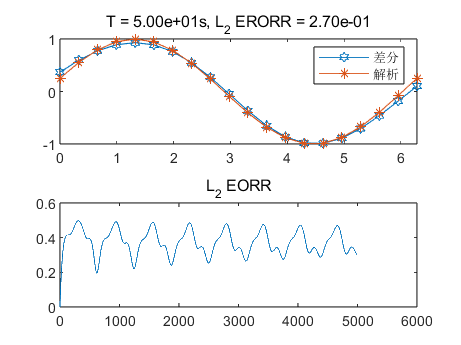



for i = 1:50:length(U)
    subplot(2,1,1)
    U_p = U(i,:); % 差分解
    showResults(U_p,x,i*h,s_x,e_x);
    
    % 打印误差变化曲线
    subplot(2,1,2)
    plot(L_2_eorr(1:i));
    title('L_2 EORR')

    pause(h)
end

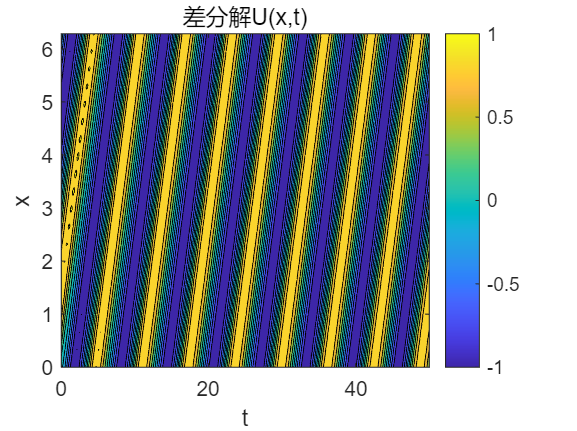

% 等高线
subplot()
[xx,tt] = meshgrid(x,T);
contourf(tt,xx,U);
title('差分解U(x,t)');
xlabel('t');
ylabel('x');
colorbar();

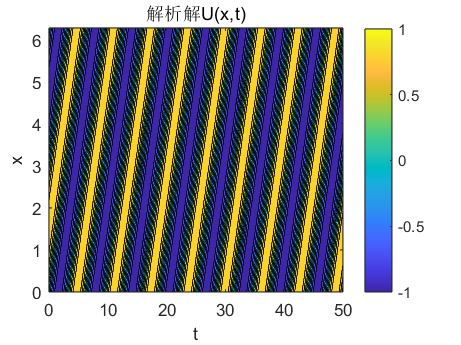

caxis_range = caxis;

subplot()
contourf(tt,xx,U_e);
title('解析解U(x,t)');
xlabel('t');
ylabel('x');
colorbar();
caxis(caxis_range);

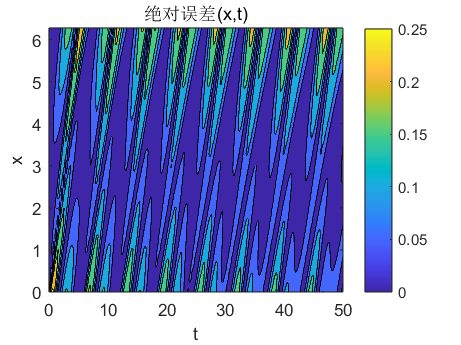


subplot()
contourf(tt,xx,abs(U_e-U));
title('绝对误差(x,t)');
xlabel('t');
ylabel('x');
colorbar();


% 可以看到，边界两端误差较大，主要是由于边界处理的方式导致的


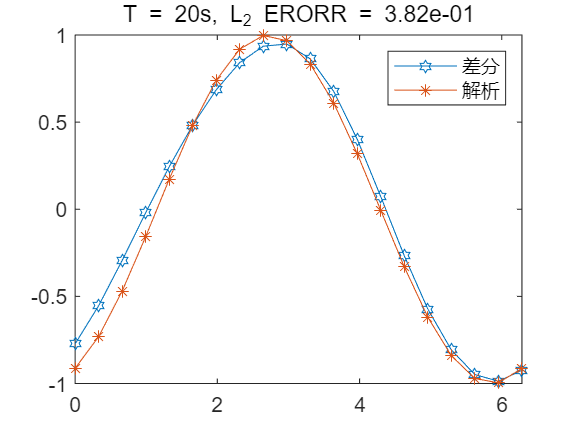

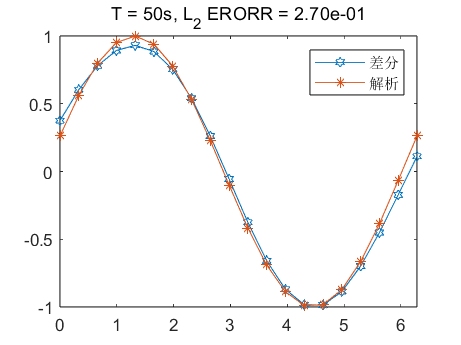

% 展示 t = 20 和 50的图像
ids = [20/h, 50/h];
for i = 1:length(ids)
    figure()
    U_p = U(ids(i),:); % 差分解
    showResults(U_p,x,ids(i)*h,s_x,e_x);
end

function t = u_x(U,d_x)
    % 计算u_x

    a = [-1/10 7/12 -5/3 1 1/6 1/60]/d_x;

    % 先对U进行扩充，增加ghost 单元，因为是6点差分，左侧需要三个点，右侧两个点
    % 所以需要左侧填充三个ghost cell，右侧两个ghost cell
    n = length(U);
    U_ = [U(1) U(1) U(1) U U(n) U(n)];
%     U_ = [0 0 0 U 0 0];
    U_copy = U_;
    
    % 只对中间的区域进行更新
    i = 4;
    while i <= n+3
        b = [U_(i-3) U_(i-2) U_(i-1) U_(i) U_(i+1) U_(i+2)]';
        U_copy(i) = a * b;
        i = i + 1;
    end
    t = U_copy(4:n+3);
end

function t = u_x_2(U,d_x)
    % 混合差分

    a = [-1/10 7/12 -5/3 1 1/6 1/60]/d_x;
    U_copy = U;
    n = length(U);
    
    i = 1;

    % 左侧边界的3个点，逆风
    while i <= 3
        U_copy(i) = (-3/2*U(i) + 2*U(i+1) - 1/2*U(i+2))/d_x;
        i = i + 1;
    end

    % 正常的差分
    while i <= n - 2
        b = [U(i-3) U(i-2) U(i-1) U(i) U(i+1) U(i+2)]';
        U_copy(i) = a * b;
        i = i + 1;
    end

    % 右侧边界的2个点，迎风
    while i <= n
        U_copy(i) = (U(i-2) - 4*U(i-1) + 3*U(i))/(2*d_x);
        i = i + 1;
    end
  
    t = U_copy;
end


function t = u_x_3(U,d_x)
    % 边界穿透

    a = [-1/10 7/12 -5/3 1 1/6 1/60]/d_x;
    n = length(U);
    U_ = [U(n-2) U(n-1) U(n) U U(1) U(2)];
    U_copy = U_;
    
    % 只对中间的区域进行更新
    i = 4;
    while i <= n+3
        b = [U_(i-3) U_(i-2) U_(i-1) U_(i) U_(i+1) U_(i+2)]';
        U_copy(i) = a * b;
        i = i + 1;
    end
    t = U_copy(4:n+3);
end

function u_t = L(U, d_x)
    % 利用runge kutta的L(u) 即 u_t = -u_x
%     u_t = -u_x(U, d_x); % ghost cell
%     u_t = -u_x_2(U, d_x); % 混合差分
    u_t = -u_x_3(U, d_x); % 边界穿透
end

function u = ref(x, t)
    % 解析解
    u = sin(x-t);
end

function showResults(U_p,x,t,s_x, e_x)
    U_e = ref(x, t); % 解析解
    plot(x,U_p,'-h',x,U_e,'-*')
    ylim([-1 1])
    xlim([s_x e_x])
    l_2_error = norm(U_p - U_e, 2);
    title(sprintf('T = %.2ds, L_2 ERORR = %.2d',t,l_2_error))
    legend('差分','解析');
end
